%======================================================================
% ECSE 443 - Final Project
% Author ----- Tristan Bouchard
% Student ID - 260747124
% Submitted -- Friday, April 12 2019, 17h00
%======================================================================
close all
clear
addpath('./Functions/');
format long

%======================================================================
% Question 1 - Single-Variable Integration
%======================================================================
syms x;
f(x) = 1/(exp(x)+exp(-x))

$$f(x) = \frac{1}{{\mathrm{e}}^{-x}+{\mathrm{e}}^{x}}$$

q1TrueVal = int(f,x,0,inf);
disp("The true value of the integral of f(x), using the" ...
    + " built-in MATLAB function int(), " + newline + "with a precision of 10^-6= " ...
    + string(vpa(q1TrueVal, 6)));

The true value of the integral of f(x), using the built-in MATLAB function int(), 
with a precision of 10^-6= 0.785398



% Using The Simpson Method, we can estimate that he value of the function
% past 100 is not relevant to the actual sum of the integral, as it is very
% close to zero
fDouble = @(x_) (1/(exp(x_)+exp(-x_)))

fDouble = function_handle with value:
    @(x_)(1/(exp(x_)+exp(-x_)))


[valSimpQ1, simpInterval] = simpsonIntegral(fDouble, 0, 30, q1TrueVal, 10^(-7));
disp("The computed value of the integral of f(x) using the Simpson " + ...
    "method = " +newline + string(vpa(valSimpQ1, 15)) +".");

The computed value of the integral of f(x) using the Simpson method = 
0.785398088205527.


disp("This result was computed using " + (length(simpInterval) -1) + " segments of length " +...
    (simpInterval(2) - simpInterval(1)) + " each.");

This result was computed using 50 segments of length 0.6 each.


%======================================================================
% Question 2 - Single-Variable Integration
%======================================================================
clear
f2Double = @(x_) (x_^3)/((1-x_^2)^(1/2));

% In order to perform this with a set amount of divisions, I had to pull
% code out of the function I wrote for assignment 4

% First, subdivide the integration area into smaller areas.
lowerBound = 0;
upperBound = 1;
% Set starting amounts
divisions = 100;
range = upperBound - lowerBound;
intervalLength = range/divisions;
intervalEnds = [lowerBound: intervalLength:upperBound];

% Create for loop, to iterate through intervals'
sum = 0;
for i = 1:(length(intervalEnds)-1)
    lb = intervalEnds(i);
    ub = intervalEnds(i+1);
    % Compute the midpoint value of the bound
    midPtVal = (ub - lb)*f2Double((ub+lb)/2);
    sum = sum + midPtVal;
end

func2Value = sum;
intervals2 = intervalEnds;

disp("The computed value of the integral of f(x) using the Mid-point " + ...
    "method = " +newline + string(vpa(func2Value, 15)) +".");

The computed value of the integral of f(x) using the Mid-point method = 
0.623775746323755.



disp("This result was computed using " + (length(intervals2) -1) + " segments of length " +...
    (intervals2(2) - intervals2(1)) + " each.");

This result was computed using 100 segments of length 0.01 each.


%======================================================================
% Question 3 - Double Variable Integration - Gauss's Law
%======================================================================
clear
% Left side of gauss, 12.4 micro Coulombs per meter
gaussLeft = 12.4 * 10^(-6);
f3line = @(xval_) 12.4 * 10^(-6);

% I choose to integrate this using the Midpoint method, as the function is
% constant.
lowerBound = -2;
upperBound = 2;
% Set starting amounts
divisions = 400;
range = upperBound - lowerBound;
intervalLength = range/divisions;
intervalEnds = [lowerBound: intervalLength:upperBound];

% Create for loop, to iterate through intervals'
sum = 0;
for i = 1:(length(intervalEnds)-1)
    lb = intervalEnds(i);
    ub = intervalEnds(i+1);
    % Compute the midpoint value of the bound
    midPtVal = (ub - lb)*f3line((ub+lb)/2);
    sum = sum + midPtVal;
end

func3Value = sum;
intervals3 = intervalEnds;

disp("The computed value of the integral of f(x) using the Mid-point " + ...
    "method = " +newline + string(vpa(func3Value, 15)) +".");

The computed value of the integral of f(x) using the Mid-point method = 
0.0000496000000000001.



disp("This result was computed using " + (length(intervals3) -1) + " segments of length " +...
    (intervals3(2) - intervals3(1)) + " each.");

This result was computed using 400 segments of length 0.01 each.


% Then, determine the pattern of the electric field caused by a wire of
% charge on a sphere of 2m in radius
% Set up initial conditions
% Copy code from Simpson method
func = @intFunc3;
lowerBoundX = 0;
upperBoundX = 2*pi;
lowerBoundY = @(x) 0;
upperBoundY = @(x) pi ;
trueValue = func3Value

trueValue =      4.960000000000009e-05


precision = 10^(-5);
stepStart = 10;

[integralRight3, intervals3] = integralSimpsonDouble(func, lowerBoundX, upperBoundX, lowerBoundY, upperBoundY, trueValue, precision, stepStart);

For 10 divisions, the integral = 4.96e-05
With an absolute error of 1.6825e-10
Elapsed time is 0.002853 seconds.



disp("The computed value of the integral of f(x) using the Simpson " + ...
    "method = " +newline + string(vpa(integralRight3, 15)) +".");

The computed value of the integral of f(x) using the Simpson method = 
0.0000496001682541567.


errorCompSimp = absoluteError(trueValue,integralRight3);
disp("The computed error between the actual result and what was computed = " + double(errorCompSimp));

The computed error between the actual result and what was computed = 1.6825e-10


disp("This result was computed using " + (length(intervals3) -1) + " segments of area " + ...
    (intervals3(2) - intervals3(1)) + " by " + (intervals3(2) - intervals3(1)) + " each.");

This result was computed using 10 segments of area 0.62832 by 0.62832 each.


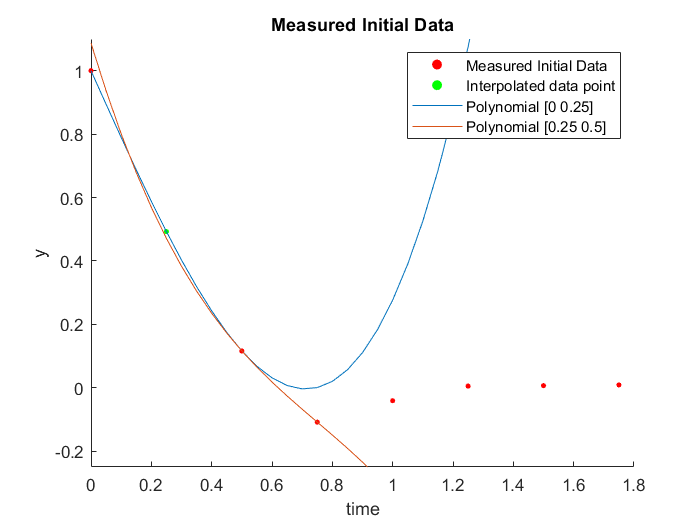

%======================================================================
% Question 4 - Second order response: Interpolation and curve fitting
%======================================================================
clear 
% u(t) = 0, -inf < t < 0
%      = 1, 0 < t < inf
time = [0 0.5 0.75 1 1.25 1.5 1.75]';
points = [1 0.1160 -0.1084 -0.0409 0.0052 0.0067 0.009]';
data = [time points];

% Use the forward and backward difference methods explored in assignment 4, as well as the
% Euler method

% First, I will interpolate using my cubic spline function from assignment
% 3 to find a value for t = 0.25.
coeff = cubicSpline(data(1, :), data(2, :), data(3, :));

t=[0:0.05:2.5];
func1 = coeff(1,1) + coeff(1,2)*t + coeff(1,3)*t.^2 + coeff(1,4)*t.^3;
func2 = coeff(2,1) + coeff(2,2)*t + coeff(2,3)*t.^2 + coeff(2,4)*t.^3;

inter = func1(6);

legendTitles = ["Measured Initial Data", "Interpolated data point"];
plotTitle = "Measured Initial Data";
yScale = [-0.25 1.1];

interp = [0.25 inter];
% Plot the data points
plotData(data, interp, "No Data", legendTitles, plotTitle, yScale);
hold on
plot(t, func1);
plot(t, func2);
legend("Measured Initial Data", "Interpolated data point", "Polynomial [0 0.25]", "Polynomial [0.25 0.5]")
hold off


% Using the interpolated data point, create new data:
time = [0:0.25:1.75]';
points = [1 inter 0.1160 -0.1084 -0.0409 0.0052 0.0067 0.009]';
data = [time points];
h = 0.25;
% Form A matrix
% We know that a particular row = [f'' f' f]
firstDevFwd = @(i) (points(i+1) - points(i))/h;
secondDevFwd = @(i) (points(i+2) - 2*points(i+1) + points(i))/(h^2);
firstDevBwd = @(i) (points(i) - points(i-1))/h;
secondDevBwd = @(i) (points(i) - 2*points(i-1) + points(i-2))/(h^2);
f = @(i) points(i);

A = [secondDevFwd(1) firstDevFwd(1) f(1);...
     secondDevFwd(2) firstDevFwd(2) f(2);...
     secondDevFwd(3) firstDevFwd(2) f(3);...
     secondDevFwd(4) firstDevFwd(2) f(4);...
     secondDevFwd(5) firstDevFwd(2) f(5);...
     secondDevFwd(6) firstDevFwd(2) f(6);...
     secondDevBwd(7) firstDevBwd(7) f(7);...
     secondDevBwd(8) firstDevBwd(8) f(8)...
    ];
siz = size(data);
yValues = ones(siz(1),1);
% solve the normalized system of equations according to the formula:
a = (A'*A)\(A'*yValues);

% Plot the newly found function

%======================================================================
% Question 5 - LU factorization
%======================================================================
clear

points = [3 -5 47 20;...
          11 16 17 10;...
          56 22 11 -18;...
          17 66 -12 7
         ];
yValues = [18 26 34 82]';






